
clc;
clear;
close all;

fontsize = 15;

%% =========================
% Parameters
% ==========================

% Fast branch: production of m_F from m_0
pf = 0.8;          % folding probability
kf = 2;            % catalytic constant
Kf = 0.5;          % Michaelis constant
kf_deg = 1;        % natural degradation of m_F

% Signal-activated consumption of m_F
gammaF = 4;        % strength of the m_0-driven consumption of m_F
KI_F   = 0.5;      % saturation constant of the inhibitory/consumption pathway

% Peak-indicator m_P
kD_prod = 1;       % production rate of m_P from m_F
KD      = 0.2;     % activation constant for m_F -> m_P
nD      = 1;       % Hill coefficient for m_F -> m_P
kD_deg  = 0;       % degradation/reset of m_P

% Reset / sequestration branch for m_P
kS = 0.15;    % production rate of m_R from m_0
KS      = 0.5;    % Michaelis constant for m_R production
kS_deg  = 0.2;    % degradation of m_R

kPR     = 10;     % sequestration rate: m_P + m_R -> complex

% Counter output m_1
kC_count = 5;      % counting rate
KC       = 0.15;   % activation threshold for m_P
nC       = 3;      % Hill coefficient for counting
kC_reset = 1.5;    % reset rate when m_P is low
KS       = 0.08;   % threshold for reset
nR       = 3;      % Hill coefficient for reset

% Communication channel parameters
M_0 = 1e4;         % transmitter concentration
D   = 4.5e-10;     % diffusion coefficient
d   = 500e-9;      % distance between emitter and receiver

Tp = 2;         % pulse duration [s]
Ts=0.01; %sampling time
fs = 1/Ts;        % sampling frequency [Hz]

% Example bit sequence
sequence = [1 0 0 0 0 0 0 0 0 0 0 0 0];

% Receiver radius
r   = 0.15e-6;
VRx = 4/3*pi*r^3;

%% =========================
% Time and transmitted signal
% ==========================

samples_per_pulse = floor(Tp * fs);
total_samples     = length(sequence) * samples_per_pulse;

t = (0:total_samples-1)' / fs;     % column vector

% Transmitted sequence
mTx = repelem(sequence, samples_per_pulse)' * M_0;

%% =========================
% Diffusion channel
% ==========================

% Avoid singularity at t = 0
t_h = t;
t_h(1) = 1/fs;

% Channel impulse response, [2, Eq. (34)]
h = VRx ./ (4*pi*D*t_h).^(3/2) .* exp(-d^2 ./ (4*D*t_h));

% Received sequence m_0
m0 = conv(h, mTx);
m0 = m0(1:length(t));

%% =========================
% State initialization
% ==========================

N  = length(t);


%% =========================
% Discrete-time simulation
% ==========================

N  = length(t);

mF = zeros(N,1);   % fast metabolite
mD = zeros(N,1);   % peak-indicator metabolite
mS = zeros(N,1);   % remover species
m1 = zeros(N,1);   % counter output

mF(1) = 0;
mD(1) = 0;
mS(1) = 0;
m1(1) = 0;

for n = 1:N-1

    dt = t(n+1) - t(n);

    % -----------------------------------
    % 1) Fast branch m_F
    % -----------------------------------
    prod_F = pf * kf * ( m0(n) / (Kf + m0(n)) );
    deg_F  = kf_deg * mF(n);
    cons_F = gammaF * mF(n) * ( m0(n) / (KI_F + m0(n)) );

    mF(n+1) = mF(n) + dt * ( prod_F - deg_F - cons_F );
    mF(n+1) = max(mF(n+1), 0);

    % -----------------------------------
    % 2) Remover species m_R
    % Produced from m_0, slower branch
    % -----------------------------------
    prod_S = kS * ( m0(n) / (KS + m0(n)) );
    deg_S  = kS_deg * mS(n);

    mS(n+1) = mS(n) + dt * ( prod_S - deg_S );
    mS(n+1) = max(mS(n+1), 0);

    % -----------------------------------
    % 3) Peak-indicator m_D
    % Activated by m_F, removed by natural decay and sequestration by m_S
    % -----------------------------------
    act_D  = (mF(n)^nD) / (KD^nD + mF(n)^nD);

    prod_D = kD_prod * act_D;
    deg_P  = kD_deg * mD(n);
    seq_P  = kPR * mD(n) * mS(n);

    mD(n+1) = mD(n) + dt * ( prod_D - deg_P - seq_P );
    mD(n+1) = max(mD(n+1), 0);

    % -----------------------------------
    % 4) Counter output m_1
    % -----------------------------------
    Hcount = (mD(n)^nC) / (KC^nC + mD(n)^nC);
    Hreset = (KS^nR)    / (KS^nR + mD(n)^nR);

    prod_C  = kC_count * Hcount;
    reset_C = kC_reset * Hreset * m1(n);

    m1(n+1) = m1(n) + dt * ( prod_C - reset_C );
    m1(n+1) = max(m1(n+1), 0);

end


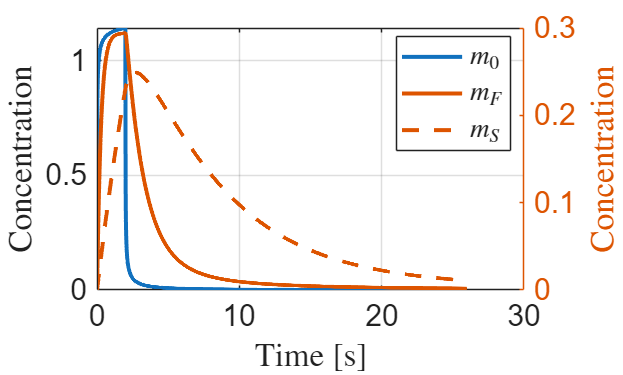


%% =========================
% Plot 1: Received signal and m_F
% ==========================

figure;
plot(t, m0, 'LineWidth', 2); hold on;
ylabel('Concentration', 'Interpreter', 'latex');
yyaxis right
plot(t, mF, 'LineWidth', 2); hold on;
plot(t, mS, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration', 'Interpreter', 'latex');
legend({'$m_0$', '$m_F$','$m_S$'}, 'Interpreter', 'latex', 'Location', 'best');
% title('Received signal and fast metabolite $m_F$', 'Interpreter', 'latex');
set(gca, 'FontSize', fontsize);
grid on;

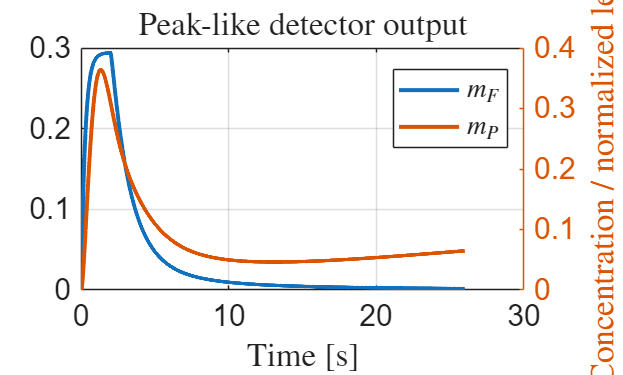


%% =========================
% Plot 2: m_F and m_D
% ==========================

figure;
plot(t, mF, 'LineWidth', 2); hold on;
yyaxis right
plot(t, mD, 'LineWidth', 2);
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration / normalized level', 'Interpreter', 'latex');
legend({'$m_F$', '$m_P$'}, 'Interpreter', 'latex', 'Location', 'best');
title('Peak-like detector output', 'Interpreter', 'latex');
set(gca, 'FontSize', fontsize);
grid on;

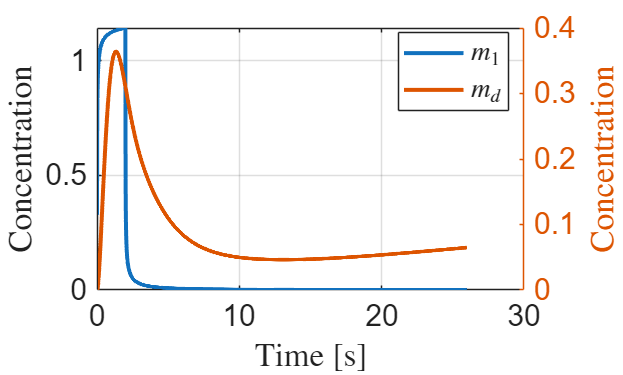


%% =========================
% Plot 3: Counter output
% ==========================

figure;
plot(t, m0, 'LineWidth', 2);
ylabel('Concentration', 'Interpreter', 'latex');
yyaxis right
plot(t, mD, 'LineWidth', 2); hold on;
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Concentration', 'Interpreter', 'latex');
legend({'$m_1$', '$m_d$'}, 'Interpreter', 'latex', 'Location', 'best');
% title('Counter output $m_1$', 'Interpreter', 'latex');
set(gca, 'FontSize', fontsize);
grid on;

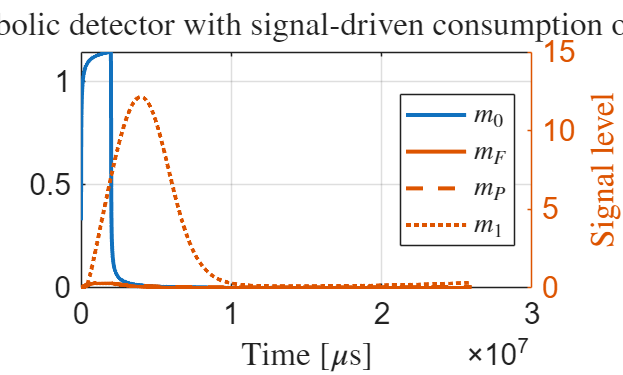


%% =========================
% Plot 4: All together
% ==========================

figure;
plot(t*1e6, m0, 'LineWidth', 2); hold on;
yyaxis right
plot(t*1e6, mF, 'LineWidth', 2);
plot(t*1e6, mD, 'LineWidth', 2);
plot(t*1e6, m1, 'LineWidth', 2);
xlabel('Time [$\mu$s]', 'Interpreter', 'latex');
ylabel('Signal level', 'Interpreter', 'latex');
legend({'$m_0$', '$m_F$', '$m_P$', '$m_1$'}, ...
    'Interpreter', 'latex', 'Location', 'best');
title('Metabolic detector with signal-driven consumption of $m_F$', ...
    'Interpreter', 'latex');
set(gca, 'FontSize', fontsize);
grid on;

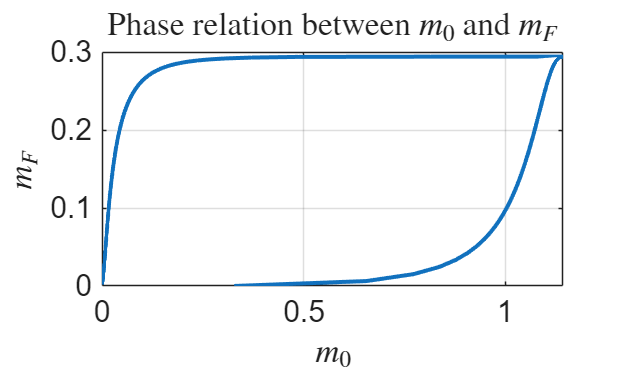


%% =========================
% Plot 5: Phase plot m_F vs m_0
% ==========================

figure;
plot(m0, mF, 'LineWidth', 2);
xlabel('$m_0$', 'Interpreter', 'latex');
ylabel('$m_F$', 'Interpreter', 'latex');
title('Phase relation between $m_0$ and $m_F$', 'Interpreter', 'latex');
set(gca, 'FontSize', fontsize);
grid on;

#### References

[1] B. Alberts, D. Bray, and K. Hopkin, *Essential Cell Biology*, 4th rev ed. edition. New York, NY: Norton & Company, 2014. 

[2] V. Jamali, A. Ahmadzadeh, W. Wicke, A. Noel, and R. Schober, "Channel Modeling for Diffusive Molecular Communication—A Tutorial Review," Proceedings of the IEEE, vol. 107, no. 7, pp. 1256–1301, Jul. 2019, doi: 10.1109/JPROC.2019.2919455.  